clear
close all
clc
addpath 'C:\GitHub\CVUT-MatLab\Resources'
tic

## Sections

crossSectionsSet.import = importdata("sectionsSet.mat");
crossSectionsSet.A = cat(1, table2array(crossSectionsSet.import.RHS(:,"A")), table2array(crossSectionsSet.import.L(:,"A")));
crossSectionsSet.Iy = cat(1, table2array(crossSectionsSet.import.RHS(:,"I_y")), table2array(crossSectionsSet.import.L(:,"I_y")));
crossSectionsSet.Iz = cat(1, table2array(crossSectionsSet.import.RHS(:,"I_z")), table2array(crossSectionsSet.import.L(:,"I_z")));
crossSectionsSet.Ip = cat(1, table2array(crossSectionsSet.import.RHS(:,"I_t")), table2array(crossSectionsSet.import.L(:,"I_t")));

sections.id = [9;6;4];
% sections.id = [9;6;6];

sections.A  = [crossSectionsSet.A(sections.id(1));crossSectionsSet.A(sections.id(2));crossSectionsSet.A(sections.id(3))];
sections.Iy = [crossSectionsSet.Iy(sections.id(1));crossSectionsSet.Iy(sections.id(2));crossSectionsSet.Iy(sections.id(3))];
sections.Iz = [crossSectionsSet.Iz(sections.id(1));crossSectionsSet.Iz(sections.id(2));crossSectionsSet.Iz(sections.id(3))];
sections.Ix = [crossSectionsSet.Ip(sections.id(1));crossSectionsSet.Ip(sections.id(2));crossSectionsSet.Ip(sections.id(3))];
sections.E  = ones(3,1) * 210*10^9;
sections.v  = ones(3,1) * 0.3;

ndisc = 7;


## Nodes

width = 2.9;
length = 2.9;
height = 3;
topHeight = 20;
nbricks = 7;
nodes.x = [[0;length;length;0];kron(ones(nbricks,1),[length/2;length;length/2;0;0;length;length;0])];                            % x coordinates of nodes
nodes.y = [[0;0;width;width];kron(ones(nbricks,1),[0;width/2;width;width/2;0;0;width;width])];                              % y coordinates of nodes
nodes.z = [0;0;0;0];
for i = 1:nbricks
    nodes.z  = [nodes.z; [height/2;height/2;height/2;height/2;height;height;height;height] + (i-1) .* [height;height;height;height;height;height;height;height]];
end
nodes.z((nbricks)*7+4:(nbricks+1)*7+4) =[topHeight-(topHeight - height*(nbricks-1))/2;topHeight-(topHeight - height*(nbricks-1))/2;topHeight-(topHeight - height*(nbricks-1))/2;topHeight-(topHeight - height*(nbricks-1))/2;topHeight;topHeight;topHeight;topHeight]; % z coordinates of nodes
nnodes = numel(nodes.x); 

## Supports

kinematic.x.nodes = [1;2;3;4];              % node indices with restricted x-direction displacements
kinematic.y.nodes = [1;2;3;4];              % node indices with restricted y-direction displacements
kinematic.z.nodes = [1;2;3;4];              % node indices with restricted z-direction displacements
kinematic.rx.nodes = [];                    % node indices with restricted x-direction displacements
kinematic.ry.nodes = [];                   % node indices with restricted y-direction displacements
kinematic.rz.nodes = [];                    % node indices with restricted z-direction displacements

nodes.dofs = true(nnodes,6);                % no kinematic boundary conditions
nodes.dofs(kinematic.x.nodes,1) = false;    % mark prevented movement in x-direction
nodes.dofs(kinematic.y.nodes,2) = false;    % mark prevented movement in y-direction
nodes.dofs(kinematic.z.nodes,3) = false;    % mark prevented movement in z-direction
nodes.dofs(kinematic.rx.nodes,4) = false;    % mark prevented movement in x-direction
nodes.dofs(kinematic.ry.nodes,5) = false;    % mark prevented movement in y-direction
nodes.dofs(kinematic.rz.nodes,6) = false;    % mark prevented movement in z-direction

## Beams

modulNodes1 = [1;2;3;4; 1;5;2;5;2;6;3;6;3;7;4;7;4;8;1;8; 9;10;11;12  ];   % elements starting nodes
beams.nodesHead = (reshape(kron(modulNodes1', ones(nbricks, 1))', 1, [])' ...
        + repelem((0:nbricks-1)', numel(modulNodes1))*8);
% beams.nodesHead = modulNodes1;
modulNodes2 = [9;10;11;12; 5;10;5;9;6;11;6;10;7;12;7;11;8;9;8;12; 10;11;12;9  ];   % elements ending nodes
beams.nodesEnd = (reshape(kron(modulNodes2', ones(nbricks, 1))', 1, [])' ...
        + repelem((0:nbricks-1)', numel(modulNodes2))*8);
% beams.nodesEnd = modulNodes2;
nr = numel(beams.nodesHead);

### Beams sections

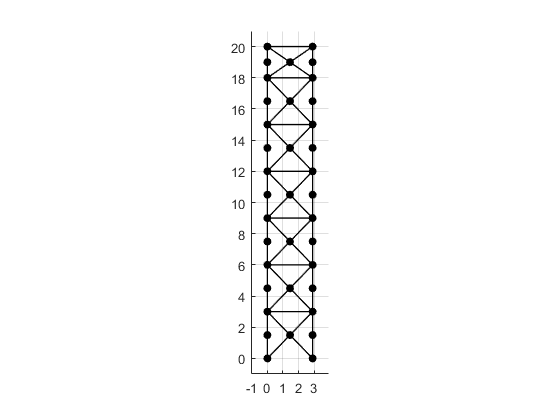

beams.disc      = ones(nr,1)*ndisc;
modulElemGroup = [1;1;1;1; 3;3;3;3;3;3;3;3;3;3;3;3;3;3;3;3;    2;2;2;2];
beams.sections = reshape(kron(modulElemGroup', ones(nbricks, 1))', 1, [])';

beams.angles = 0 * reshape(kron([0;0;0;0; 1;1;-1;-1;1;1;-1;-1;1;1;-1;-1;1;1;-1;-1; 0;0;0;0 ]', ones(nbricks, 1))', 1, [])';
ng = max(max(beams.sections));
plot3([nodes.x(beams.nodesHead) nodes.x(beams.nodesEnd)]', ...
     [nodes.y(beams.nodesHead) nodes.y(beams.nodesEnd)]', ...
     [nodes.z(beams.nodesHead) nodes.z(beams.nodesEnd)]', ...
     'k','LineWidth',1);
hold on;
scatter3(nodes.x, nodes.y, nodes.z, 'black', 'filled', 'o');
axis equal;
xlim([min(nodes.x)-1,max(nodes.x)+1]);  % to avoid tight limits
ylim([min(nodes.y)-1,max(nodes.y)+1]);  % to avoid tight limits
zlim([min(nodes.z)-1,max(nodes.z)+1]);  % to avoid tight limits
grid on

## Loads

% loads.x.nodes = [1;2;3;4]+(nbricks)*8;             % node indices with x-direction forces
% loads.x.value = [-10000;-10000;-10000;-10000];             % magnitude of the x-direction forces
% loads.y.nodes = reshape((repmat([1,2], nbricks, 1) + (1:nbricks)'*8).',1,[])';          % node indices with y-direction forces
% loads.y.value = ones(nbricks*2,1)*0.25;          % magnitude of the y-direction forces 
% loads.z.nodes = [1;2;3;4]+(nbricks)*8;             % node indices with z-direction forces
% loads.z.value = [-10000;-10000;-10000;-10000];
loads.y.nodes = reshape((repmat([1,2], nbricks, 1) + (1:nbricks)'*8).',1,[])';             % node indices with x-direction forces
loads.y.value = ones(nbricks*2,1)*0.25;             % magnitude of the x-direction forces
loads.x.nodes = [1;2;3;4]+(nbricks)*8;             % node indices with y-direction forces
loads.x.value = [-10;-10;-10;-10]*10^3;             % magnitude of the y-direction forces 
loads.z.nodes = [1;2;3;4]+(nbricks)*8;             % node indices with y-direction forces
loads.z.value = [-10;-10;-10;-10]*10^3;             % magnitude of the y-direction forces 

loads.rx.nodes = [];          % node indices with x-direction forces
loads.rx.value = [];          % magnitude of the x-direction forces
loads.ry.nodes = [];          % node indices with y-direction forces
loads.ry.value = [];          % magnitude of the y-direction forces 
loads.rz.nodes = [];          % node indices with z-direction forces
loads.rz.value = []; 
% scatter3(nodes.x(loads.x.nodes), nodes.y(loads.x.nodes), nodes.z(loads.x.nodes), 'red', 'filled', 'o');
% scatter3(nodes.x(loads.x.nodes)-1, nodes.y(loads.x.nodes), nodes.z(loads.x.nodes), 'green', 'filled', 'o');
hold off;

## Force vector

forceVector = sparse([loads.x.nodes*6-5; loads.y.nodes*6-4; loads.z.nodes*6-3;loads.rx.nodes*3-2; loads.ry.nodes*3-1; loads.rz.nodes*3], ...
                     1, ...
                     [loads.x.value; loads.y.value; loads.z.value;loads.rx.value; loads.ry.value; loads.rz.value], ...
                     nnodes*6, 1);
f = forceVector(reshape(reshape(nodes.dofs.',[],1).', 1, [])');
% f = full(f)

## FEM

nodes.ndofs = sum(sum(nodes.dofs));
nodes.nnodes    = nnodes;

beams.nbeams  = nr;
beams.vertex = beamVertexFn(beams,nodes);
beams.codeNumbers = codeNumbersFn(beams,nodes);
beams.XY = XYtoRotBeamsFn(beams,beams.angles);

elements = discretizationBeamsFn(beams,nodes);
elements.XY = XYtoElementFn(beams);
elements.sections = sectionToElementFn(sections,beams);
elements.ndofs = max(max(elements.codeNumbers));



%------------------------------------------------------------------------
%   Linear analysis
%------------------------------------------------------------------------
endForces.global = sparse(elements.ndofs,1);
endForces.global(1:max(max(beams.codeNumbers))) = f;

transformationMatrix = transformationMatrixFn(elements);

stiffnesMatrix = stiffnessMatrixFn(elements,transformationMatrix);

[endForces.local, displ] = EndForcesFn(stiffnesMatrix,endForces,transformationMatrix,elements);
%------------------------------------------------------------------------
%   Non-linear analysis
%------------------------------------------------------------------------
geometricMatrix = geometricMatrixFnV2(elements,transformationMatrix,endForces);
% geometricMatrix = geometricMatrixFn(elements,transformationMatrix,endForces);

% [geometricMatrix.local,geometricMatrix.global] = geometricMoofemFn(elements.sections.A,...
%          elements.sections.Ix,transformationMatrix.matrices,transformationMatrix.lengths,endForces.local,elements.ndofs,...
%          elements.nelement,elements.codeNumbers,12);

volume = sum(elements.sections.A .* transformationMatrix.lengths)
% 
Results = criticalLoadFn(stiffnesMatrix,geometricMatrix);
% 
[sortedValues,sortedVectors]= sortValuesVectorFn(Results.values,Results.vectors);

% SortedResults = criticalLoadFnV2(stiffnesMatrix,geometricMatrix);

disp('1. kritické břemeno')
disp([num2str(sortedValues(1)),' N'])
disp('2. kritické břemeno')
disp([num2str(sortedValues(2)),' N'])
disp('3. kritické břemeno')
disp([num2str(sortedValues(3)),' N'])
disp('4. kritické břemeno')
disp([num2str(sortedValues(4)),' N'])
disp('5. kritické břemeno')
disp([num2str(sortedValues(5)),' N'])
disp('6. kritické břemeno')
disp([num2str(sortedValues(6)),' N'])
disp('7. kritické břemeno')
disp([num2str(sortedValues(7)),' N'])
disp('8. kritické břemeno')
disp([num2str(sortedValues(8)),' N'])
disp('9. kritické břemeno')
disp([num2str(sortedValues(9)),' N'])
disp('10. kritické břemeno')
disp([num2str(sortedValues(10)),' N'])
toc


for i = 1:nr
    idR = 1:12;
    idC = (i-1)*ndisc + 1 : i*ndisc;
    
    % Vytvoření podmatice
    endForces.beams{i} = endForces.local(idR, idC);
    N(1,i)=endForces.beams{i}(7,1);
    N(2,i)=endForces.beams{i}(8,1);
    N(3,i)=endForces.beams{i}(9,1);
    displ.beams{i} = displ.local(idR, idC);
end
N = N'/1000;
for neig=1:10
    nf = size(f,1);
    supports=reshape(sortedVectors(1:12,neig),3,4)';
    free=reshape(sortedVectors(13:nf,neig), 6, [])';
    nfree = size(free);
    
    koko(1:4,1:3) = 0;
    koko(1:4,4:6) = supports;
    koko(5:nfree(1)+4,1:nfree(2))= free;
    norm = max(max(abs(koko)));
    eigVectors{neig} = koko/norm;
end

OOFEM = [ 5.76053073e+00 ; -6.66232871e+00 ; 8.33662720e+00 ; 8.53074621e+00 ; 8.91879175e+00 ; 9.21681741e+00 ; 9.49093085e+00 ; -9.86922448e+00 ; -9.95996443e+00 ; -1.03632693e+01 ];